# **Econometrics 2 (Fall 2025)**

## **Homework 1: Probit & Logit**

### **Due Wednesday on Sept. 01, 2025.**

**Xiaolin Yang, TA**

**This code estimates a discrete (binary) choice model using Maximum Likelihood. The latent variable model is:**

                                                                $y_i = \beta_0 + \beta_1 x_i + u_i$ ,

                                                                
$$z_i = \begin{cases} 1 &\text{if } y_i > 0\\ 0 &otherwise\end{cases}$$
 

**with **$u_i$ **follows a standard normal (probit) or a standard logistic distribution (logit).**

### Question 1: Simulate and estimate a probit model

#### 1. Set the parameters.

There are 100 simulations with 300 observations per simulation. With probit model, $u_i \sim N(0, \sigma)$.

Set $\beta_0 = 0.5, \beta_1 = 3$ and $\sigma = 1$.

close all
clear
clc


N = 300;                           % Number of observations.
beta0 = 0.5;                       % Intercept.
beta1 = 3;                         % Coefficient on X.
sigma = 1;                         % Standard deviation.

b_true = [beta0; beta1];
b0 = [1 1];                        % initial guess

sim = 100;                         % Number of simulations.
results_mat = zeros(sim, 2);       % Results matrix.
results_mat_logit = results_mat;                                  

#### 2. Maximum Likelihood Estimation.

In each simulation, generate draw the error terms, $U$, from the standard normal distribution and generate the data, $X, Y$ and $Z$. Estimate the model using Maximum Likelihood and record the estimates.

x = ((1:N)'./N).*normrnd(0,1,N,1);                          
X = [ones(size(x,1),1) x];
options = optimset('Display','off');                     


for s = 1:sim
    
    u = normrnd(0,sigma,N,1);          % Generate U.
    y = X * b_true + u;                % Generate Y.
    z = double((y > 0));               % Generate Z.
    
    [b_mle, ~, ~, ~, ~, hess] = fminunc(@(b) logl_probit(b,X,z), b0, options); 

    results_mat(s, 1:size(results_mat,2)) = b_mle;     
    vmat = inv(hess);
    
end

#### 3. Display the results of the last simulation.

T_last = array2table([ ...
    b_mle(1), sqrt(vmat(1,1));
    b_mle(2), sqrt(vmat(2,2))], ...
    'VariableNames', {'Estimate','StdError'}, ...
    'RowNames', {'Beta0','Beta1'});
disp(T_last)

             Estimate    StdError
             ________    ________

    Beta0    0.49679     0.09944 
    Beta1     3.3335     0.40757 



#### 4. Empirical results (average across simulations).

T_emp = array2table([ ...
    mean(results_mat(:,1)), std(results_mat(:,1));
    mean(results_mat(:,2)), std(results_mat(:,2))], ...
    'VariableNames', {'Mean','StdDev'}, ...
    'RowNames', {'Beta0','Beta1'});

disp(T_emp)

              Mean      StdDev 
             _______    _______

    Beta0    0.52021    0.12156
    Beta1     3.1018    0.41049



#### 5. Plot the estimated coefficients from all simulations.

Plot a histogram of $\beta_0$.

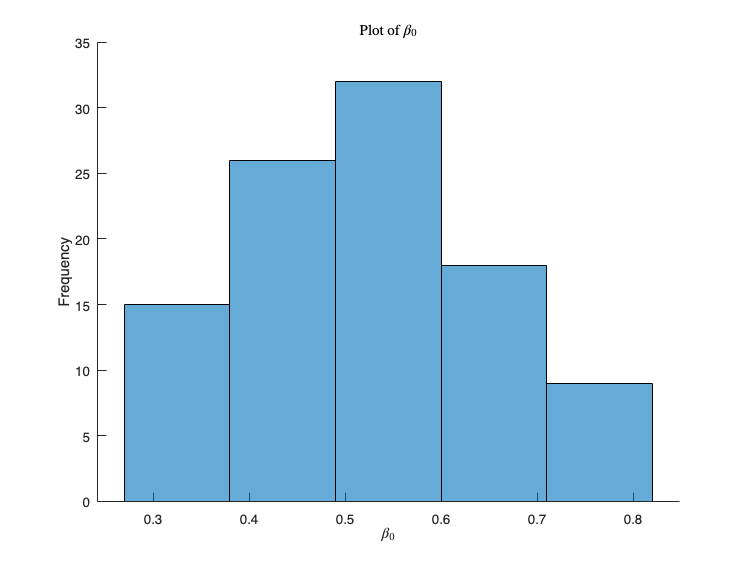

figure(1)
hold on
histogram(results_mat(:,1),5)
xlabel('$\beta_{0}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{0}$','interpreter','LaTex')
hold off

Plot a histogram of $\beta_1$.

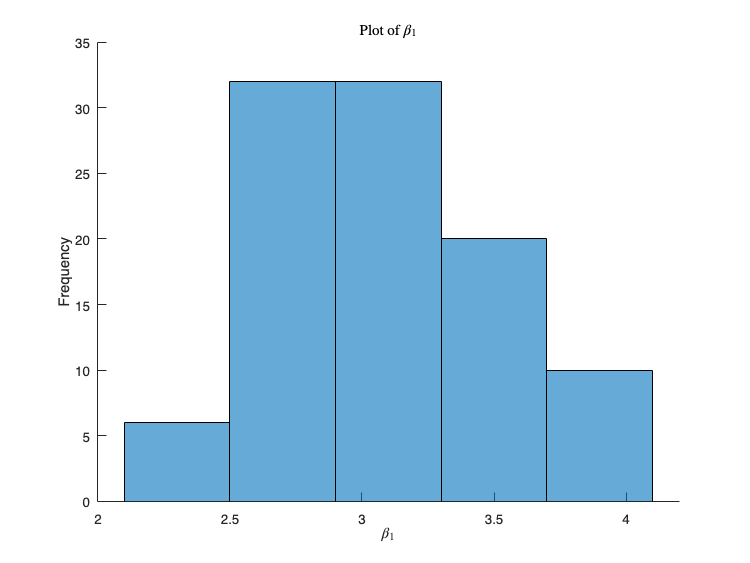

figure(2)
hold on
histogram(results_mat(:,2),5)
xlabel('$\beta_{1}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{1}$','interpreter','LaTex')
hold off

### Question 2: Estimate the parameters using a logit model

Now estimate the parameters using a logit model, while still simulate the model using the normal draws. The paramters and the codes mostly remain the same, only the likelihood function will be a little different.

for s = 1:sim

    u = normrnd(0,sigma,N,1);                          
    y = X * b_true + u;                                
    z = double((y > 0));                                
    
    [b_mle_logit, ~, ~, ~, ~, hess_logit] = fminunc(@(b) logl_logit(b, X, z), b0, options);  
    
    results_mat_logit(s, 1:size(results_mat,2)) = b_mle_logit';       
    vmat_logit = inv(hess_logit);
    
end


#### Display the emperical results (average across all simulations)

T_emp_logit = array2table([ ...
    mean(results_mat_logit(:,1)), std(results_mat_logit(:,1));
    mean(results_mat_logit(:,2)), std(results_mat_logit(:,2))], ...
    'VariableNames', {'Mean','StdDev'}, ...
    'RowNames', {'Beta0','Beta1'});

disp(T_emp_logit)

              Mean      StdDev 
             _______    _______

    Beta0    0.85044    0.18907
    Beta1     5.1759    0.58703



#### Are the parameters different?

Yes, the results are different.

#### The marginal effect evaluated at the data mean:

In an index model, the marginal effect function is $\frac{\partial}{\partial x}P(x) = \beta g(x'\beta)|_{x = \bar x}$, where $g(\cdot)$ is the density function.

I use the coefficients from the last simulation to obtain the marginal effects (I think you can choose other simulations or (say) the average, but this shouldn't matter much).

X_bar = mean(X);

ME_probit = normpdf(X_bar * b_mle') * b_mle'; 
ME_logit = exp(X_bar * b_mle_logit')/(1+ exp(X_bar * b_mle_logit'))^2 * b_mle_logit';

Alternatively, I use the avergae coefficients across simulations to obtain the marginal effect at data mean; I think this can reduce simulation noise.

avg_b_probit = mean(results_mat,1);
avg_b_logit = mean(results_mat_logit,1);

ME_probit2 = normpdf(X_bar * avg_b_probit') * avg_b_probit'; 
ME_logit2 = exp(X_bar * avg_b_logit')/(1+ exp(X_bar * avg_b_logit'))^2 * avg_b_logit';

ME = array2table([ME_probit2  ME_logit2], ...
    'VariableNames', {'Probit','Logit'}, ...
    'RowNames', {'Beta0','Beta1'});

disp(ME)

             Probit      Logit 
             _______    _______

    Beta0    0.18012    0.17691
    Beta1      1.074     1.0767



  Now, we can see that the marginal effects obtained from these two models are similar.

### Question 3: Standard errors in three ways:

For this part, I followed Chapter 25 of Hansen, see page 816-817, Equations (25.6)-(25.7)

Also, we manipulate the size of the sample to comapre the results.

N_vec = [100 1000 5000];                   % Small/medium/large sample sizes
results = zeros(sim,2,size(N_vec,2));       % Estimates 
se_mat_h_ana = zeros(sim,2,size(N_vec,2));  % Analytical hessian se
se_mat_h_num = zeros(sim,2,size(N_vec,2));  % Numerical hessian se
se_mat_ops = zeros(sim,2,size(N_vec,2));    % Outer product of the gradient

For each sample size, repeat what we did in question 1, draw errors, generate data and then estimate. An extra layer of for loop is used.

for n = 1:size(N_vec,2)
    ss = N_vec(n);                          % sample size
    x = ((1:ss)'./ss).*normrnd(0,1,ss,1);   % Generate X.
    X = [ones(ss,1),x];                     % Include intercept.
    
    for s = 1:sim
        
        u = normrnd(0,sigma,ss,1);               
        y = X*b_true + u;                        
        z = double((y>0));                                            
        
        [b_mle,~,~,~,~,hess] = fminunc(@(b) logl_probit(b,X,z), b0,options);   
        
        % Store estimates.
        results(s,:,n) = b_mle';                                            
        vmat_h_num = inv(hess);                                             
        vmat_h_ana = inv(hess_analytical(b_mle,X,z));                      
        vmat_ops = inv(OP(b_mle,X,z));                                     
        
        se_mat_h_num(s,:,n) = sqrt(diag(vmat_h_num))';  
        se_mat_h_ana(s,:,n) = sqrt(diag(vmat_h_ana))';  
        se_mat_ops(s,:,n) = sqrt(diag(vmat_ops));       
        
    end
end

## Empirical results.

For each parameter, I report five statistics in columns: (1) the mean of the estimates across simulations, (2) their standard deviation, and (3)–(5) the average standard errors computed using three different methods—based on the analytical Hessian, the numerical Hessian, and the outer product of scores, respectively.

% Small sample size
T_small = array2table([ ...
    mean(results(:,1,1)), std(results(:,1,1)), mean(se_mat_h_ana(:,1,1)), mean(se_mat_h_num(:,1,1)), mean(se_mat_ops(:,1,1));
    mean(results(:,2,1)), std(results(:,2,1)), mean(se_mat_h_ana(:,2,1)), mean(se_mat_h_num(:,2,1)), mean(se_mat_ops(:,2,1))], ...
    'VariableNames', {'Mean','StdDev','SE_Ana','SE_Num','SE_OPS'}, ...
    'RowNames', {'Beta0','Beta1'});

% Medium sample size
T_med = array2table([ ...
    mean(results(:,1,2)), std(results(:,1,2)), mean(se_mat_h_ana(:,1,2)), mean(se_mat_h_num(:,1,2)), mean(se_mat_ops(:,1,2));
    mean(results(:,2,2)), std(results(:,2,2)), mean(se_mat_h_ana(:,2,2)), mean(se_mat_h_num(:,2,2)), mean(se_mat_ops(:,2,2))], ...
    'VariableNames', {'Mean','StdDev','SE_Ana','SE_Num','SE_OPS'}, ...
    'RowNames', {'Beta0','Beta1'});

% Large sample size
T_large = array2table([ ...
    mean(results(:,1,3)), std(results(:,1,3)), mean(se_mat_h_ana(:,1,3)), mean(se_mat_h_num(:,1,3)), mean(se_mat_ops(:,1,3));
    mean(results(:,2,3)), std(results(:,2,3)), mean(se_mat_h_ana(:,2,3)), mean(se_mat_h_num(:,2,3)), mean(se_mat_ops(:,2,3))], ...
    'VariableNames', {'Mean','StdDev','SE_Ana','SE_Num','SE_OPS'}, ...
    'RowNames', {'Beta0','Beta1'});

**Small sample size results (**$N=100$**):**

disp(T_small)

              Mean      StdDev     SE_Ana     SE_Num     SE_OPS 
             _______    _______    _______    _______    _______

    Beta0    0.51115    0.18316    0.17342    0.17342     0.1782
    Beta1     3.2911    0.79419    0.71006    0.71014    0.80417



**Medium sample size results (**$N=1000$)**:**

disp(T_med)

              Mean       StdDev      SE_Ana      SE_Num     SE_OPS 
             _______    ________    ________    ________    _______

    Beta0    0.51134    0.061374    0.052312    0.052313    0.05244
    Beta1     3.0375     0.19578     0.19968      0.1997    0.20259



**Large sample size results (**$N=10,000
$**):**

disp(T_large)

              Mean       StdDev      SE_Ana      SE_Num      SE_OPS 
             _______    ________    ________    ________    ________

    Beta0    0.49991    0.023001    0.023628    0.023629    0.023628
    Beta1     2.9992    0.084671    0.087089    0.087098    0.087258



## Define the likelihood function

function L = logl_probit(b, X, z)
Xb = X * b';
L = -sum(z .* log(normcdf(Xb)) + (1-z) .* log(normcdf(-Xb)));
end

function L = logl_logit(b, X, z)
Xb = X * b';
L = -sum(z .* log(cdf('Logistic',Xb)) + (1-z) .* log(cdf('Logistic',-Xb)));
end